# Driver Final

close all; clear; clc;

% constants 
mu = 3.986004418*10^14; % in meters cubed per seconds squared
% setup
Ri = [1131.34; -2282.343; 6672.423]; % units: km
Vi = [-5.64305; 4.30333; 2.42879]; % units km/s

% convert km to m
Ri = Ri * 1000;
Vi = Vi * 1000;

% convert 24 hours to seconds
t = 24*60*60; % (hr*60 = min, min*60 = s) 

dtList = [.1,1,10,60,300];

## a) euler integration of position and velocity

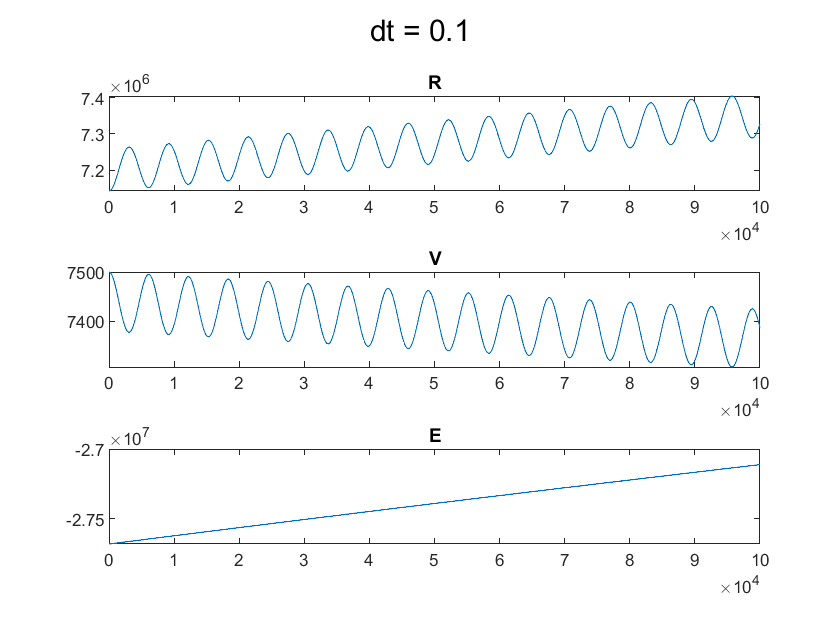

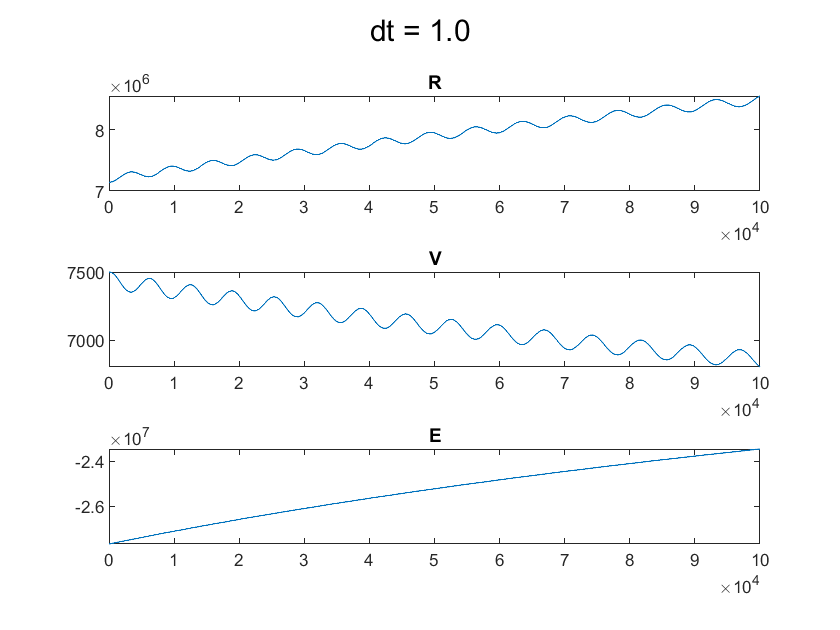

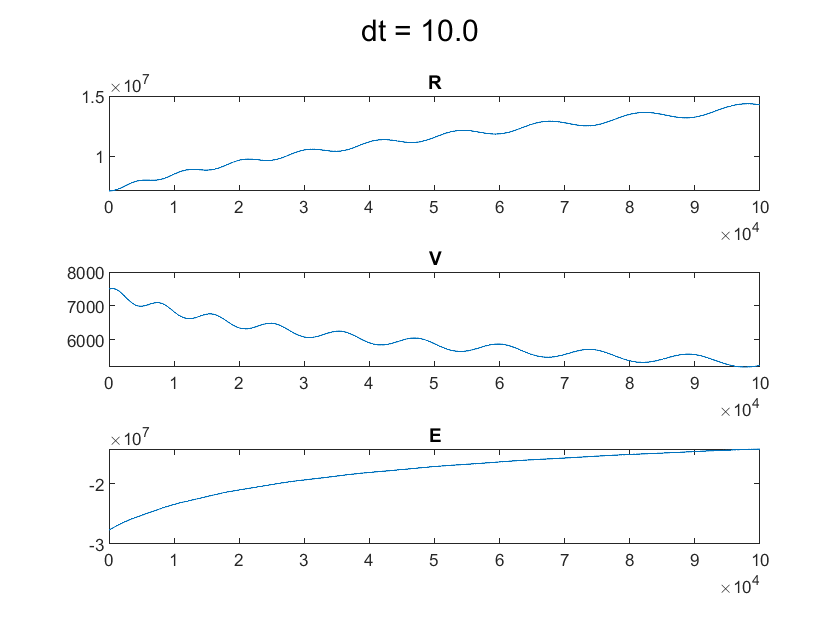

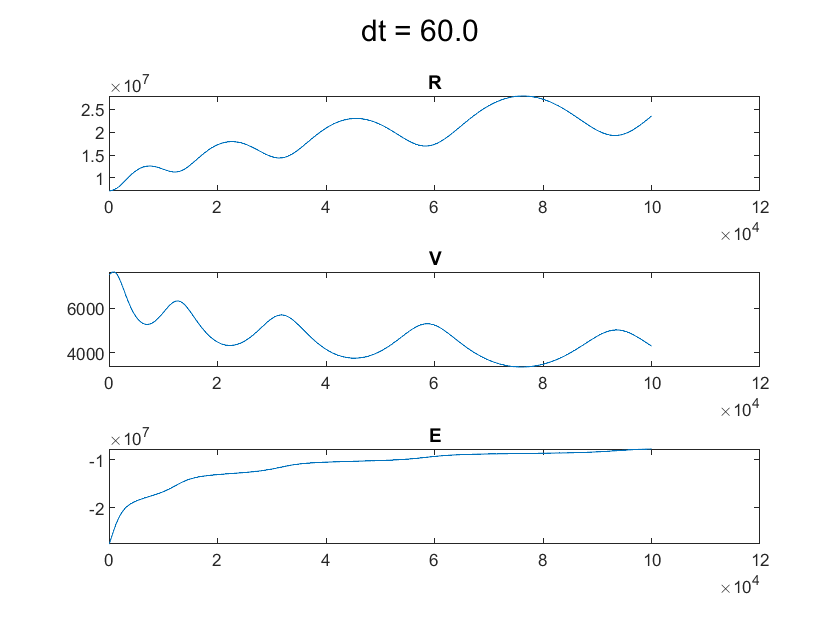

for i = 1:length(dtList)
    dt = dtList(i);
    [R,V,E,h, time] = integrate2Body3D(Ri,Vi,100000,dt);
    figure; sgtitle(sprintf("dt = %3.1f",dt));
    subplot(3,1,1); plot(time,R); title("R"); subplot(3,1,2); plot(time,V); title("V"); subplot(3,1,3); plot(time,E); title("E");%for debug
    %subplot(1,3,1); plot(R); title("R"); subplot(1,3,2); plot(V); title("V"); subplot(1,3,3); plot(E); title("E");%for debug
    %figure; subplot(1,4,1); plot(R); title("R"); subplot(1,4,2); plot(V); title("V"); subplot(1,4,3); plot(E); title("E"); subplot(1,4,4); plot(h); title("h");
    %figure; plot(h); title("h");
end


fprintf("one noticable differance in euler integration with larger timesteps is that ailiasing occures.\n"+"Another is that the error (wich can be measured by the change in energy (as energy should be a constant) increases as step size grows).\n");

one noticable differance in euler integration with larger timesteps is that ailiasing occures.
Another is that the error (wich can be measured by the change in energy (as energy should be a constant) increases as step size grows).


fprintf("with a step size of .1s error is in the range of .05*10^7 energy and with the step size of 300s change in energy is in the order of 2*10^7."+"\n"+"in short a small step size is more acturate and is less likely to have ailiasing; however it will run slower than a larger step size.")

with a step size of .1s error is in the range of .05*10^7 energy and with the step size of 300s change in energy is in the order of 2*10^7.
in short a small step size is more acturate and is less likely to have ailiasing; however it will run slower than a larger step size.

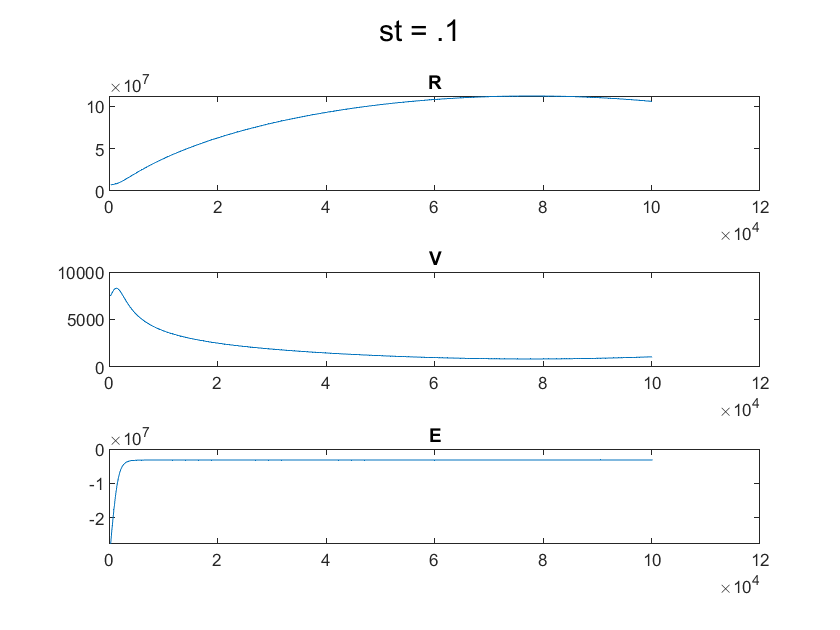

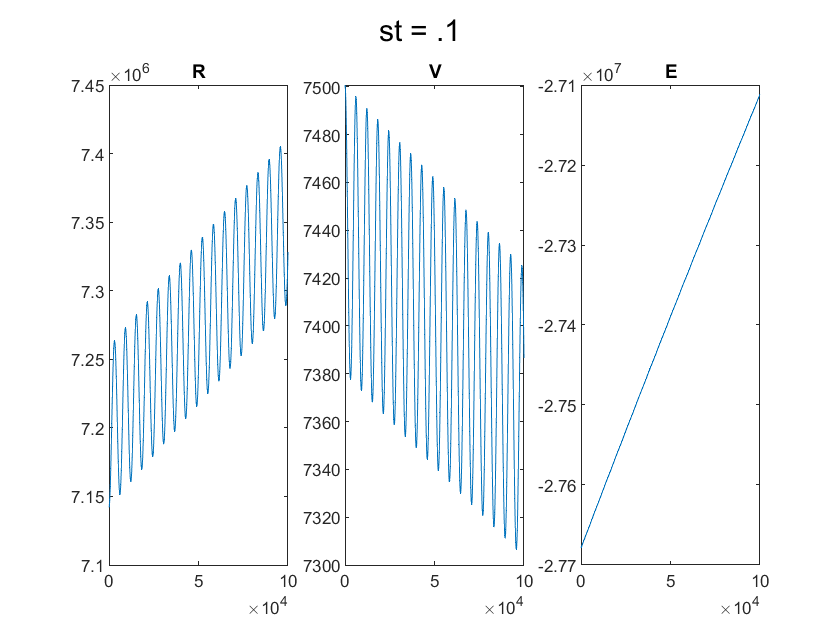


%calculate it all over again for the comparison with newtons method
dt = .1; % TODO: use the given values
[R,V,E,h,time] = integrate2Body3D(Ri,Vi,100000,dt);
sgtitle("st = .1"); subplot(1,3,1); plot(time,R); title("R"); subplot(1,3,2); plot(time,V); title("V"); subplot(1,3,3); plot(time,E); title("E");%for debug

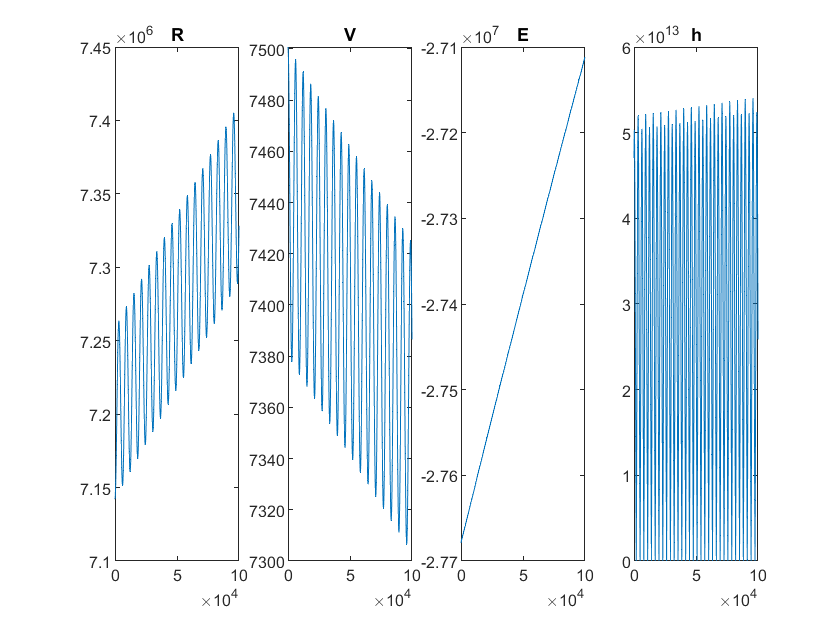

figure; subplot(1,4,1); plot(time,R); title("R"); subplot(1,4,2); plot(time,V); title("V"); subplot(1,4,3); plot(time,E); title("E"); subplot(1,4,4); plot(time,h); title("h");

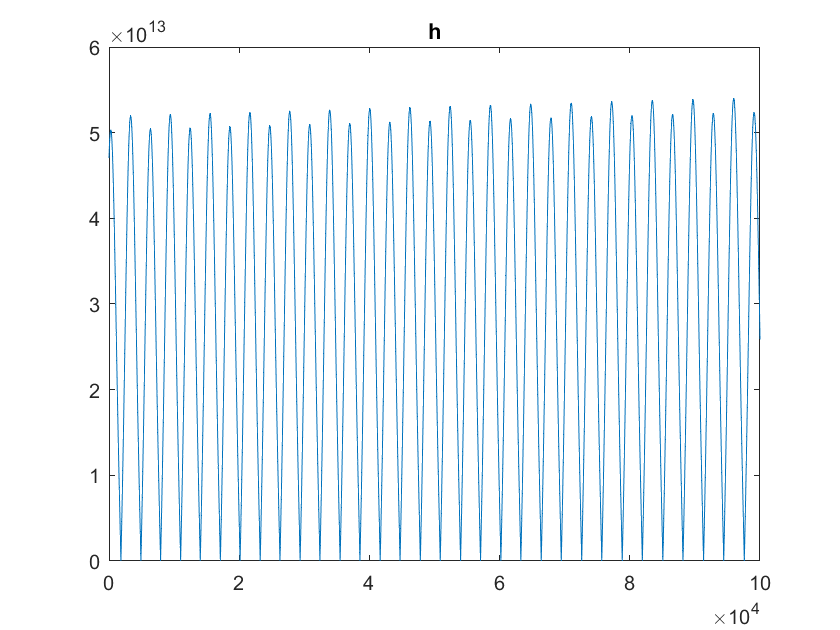

figure; plot(time,h); title("h");

## b) RV to COE, kepler's euqation, and COE to RV

[a,e,i,RA,w,nu] = rv2coe(Ri,Vi); %TODO: get create  version of this equation

e = norm(e); % we will use e as a scalar (it's magnitude) not as a vetor
n = sqrt(mu/a^3);
Ei = atan2(sqrt(1-e^2)*sin(nu), e+cos(nu)); % auto quadrent check
%Ei = acos(e+cos(nu) / (1+e*cos(nu))); % need manual quadrent check TODO: implement quad check if using this
Mi = Ei - e*sin(Ei);
Mf = Mi + n*t; %Mi+n*deltaT

%Eold = Mf; %by hand method
%Ef = Mf + e*sin(Eold); %by hand method
if (-pi<Mf && Mf<0 || Mf>pi)
    Eold = Mf - e;
else
    Eold = Mf + e;
end
Ef = Eold - (Mf-Eold+e*sin(Eold)) / (-1+e*cos(Eold)); %newton method
while(abs(Ef-Eold) > 1e-6)
    Eold = Ef;
    %Ef = Mf + e*sin(Ef); %by hand method 
    Ef = Eold - (Mf-Eold+e*sin(Eold)) / (-1+e*cos(Eold)); %newton method
end
Mf;
nuf = atan2(sqrt(1-e^2)*sin(Ef), cos(Ef)-e); % auto quadrent check
%by hand method nuf = 1.3285 ef = 1.3207
%newton raphson nuf = 1.3285 ef = 89.2853 mod 2pi = 1.3207

[Rn, Vn] = coe2rv(a,e,i,RA,w,nuf);

En = (1/2)*norm(Vn)^2-mu/norm(Rn);
hn = norm(cross(Rn,Vn));

## c) comparison of a) and b)

Ei = (1/2)*norm(Vi)^2-mu/norm(Ri);



disp("comparison of final vlaues")

comparison of final vlaues


disp("euler")

euler


disp("R = " + R(end))

R = 7328286.8999


disp("V = " + V(end))

V = 7386.5511


disp("E = " + E(end))

E = -27111466.9943


disp("h = " + h(end))

h = 25867846862621.34


disp("Newton")

Newton


disp("R = " + norm(Rn))

R = 7186034.1717


disp("V = " + norm(Vn))

V = 7469.915


disp("E = " + En)

E = -27568950.2776


disp("h = " + hn)

h = 53677411134.3446


disp("initial E")

initial E


disp("E = " + Ei)

E = -27678777.1928


disp("change in E")

change in E


fprintf("Euler: %d\n",abs(Ei-E(end)));

Euler: 5.673102e+05


fprintf("Newton: %d\n",abs(Ei-En));

Newton: 1.098269e+05


fprintf("Newton is %2.1f percent more acurate than euler\n",abs(Ei-E(end))/abs(Ei-En))

Newton is 5.2 percent more acurate than euler



fprintf("Differance in Position: %d\n",abs(R(end)-norm(Rn)));

Differance in Position: 1.422527e+05


fprintf("Differance in Velocity: %d\n",abs(V(end)-norm(Vn)));

Differance in Velocity: 8.336387e+01


fprintf("Differance in Specific Energy: %d\n",abs(E(end)-En));

Differance in Specific Energy: 4.574833e+05


fprintf("Differance in Specific Angular Momentum: %d\n",abs(V(end)-norm(Vn)));

Differance in Specific Angular Momentum: 8.336387e+01



fprintf("on the whole newtons method is more acurate than the the euler integration, one advantage the eulers method does have however is that it shows you the entire path not just the point in question.")

on the whole newtons method is more acurate than the the euler integration, one advantage the eulers method does have however is that it shows you the entire path not just the point in question.

function [R,V,E,h,time] = integrate2Body3D(Ri,Vi,t,dt)
    mu = 3.986004418*10^14;
    
    timesteps = ceil(t/dt);
    time = (1:timesteps)*dt;
    
    R = zeros(1,timesteps);
    V = zeros(1,timesteps);
    h = zeros(1,timesteps);
    X = [Ri(1); Ri(2); Ri(3); Vi(1); Vi(2); Vi(3)]; %X = [x; y; z; vx; vy; vz];
    %Xd = [V(1); V(2); V(3); ax, ay, az]; %Xd = [vx; vy; vz; ax, ay, az];
    
    for i = 1:timesteps
    %using the full calculation formula instead of norm (it is alegadly faster)
    R(i) = sqrt(X(1)^2 + X(2)^2 + X(3)^2); % magnitude of position
    V(i) = sqrt(X(4)^2 + X(5)^2 + X(6)^2); % magnitude of velocity
    h(i) = norm(cross([X(1),X(2),X(3)],[X(3),X(4),X(5)]));
    
    %caclulate change in state at current time step
    fxt = [X(4); X(5); X(6); -(mu/R(i)^3)*X(1); -(mu/R(i)^3)*X(2); -(mu/R(i)^3)*X(3)]; % fxt = [vx; vy; vz; -(mu/r^3)*x; -(mu/r^3)*y; -(mu/r^3)*z];
    X = X + + fxt*dt; %Xnew = Xold + fxt*dt; % advance time 
    end
    E = (1/2).*V.^2-mu./R;
end

function [R,V] = coe2rv(a,e,i,RA,w,nu)
    %check input validity
    if (i==0) | (e==0)
        disp('warning: i = 0 or e = 0.');
    end
    
    mu = 3.986004418*10^14; % in m^3/s^2
    
    %precomute for tranfromation to perifocal
    p = a * (1-dot(e,e));
    cnu = cos(nu);
    snu = sin(nu);
    emag = norm(e);
    Rmag = norm(p)/(1+emag*cnu);
    
    Rpqw = [Rmag*cnu; Rmag*snu; 0];
    %Vpqw = [-snu; emag+cnu; 0]; %i think this losses the magnitude so it
    %must be multiplied by vmag which is found via vis viva equation
    Vpqw = sqrt(mu*(2/Rmag-1/a)).*[-snu; emag+cnu; 0];
    
    %precompute for A matrix
    sw = sin(w); cw = cos(w);
    sRA = sin(RA); cRA = cos(RA);
    si = sin(i); ci = cos(i);
    
    %define transofrmation matrix
    A = [cRA*cw-sRA*sw*ci, -cRA*sw-sRA*cw*ci, sRA*si; sRA*cw+cRA*sw*ci, -sRA*sw+cRA*cw*ci, -cRA*si; sw*si, cw*si, ci];
    
    R = A * Rpqw;
    V = A * Vpqw;
end

function [a,e,i,RA,w,nu] = rv2coe(R,V)
    r = norm(R);
    v = norm(V);
    %mu = 3.986004418 * 10^5; %in km^3/s^2
    mu = 3.986004418*10^14; % in m^3/s^2
    E = v^2/2 - mu/r;
    
    % do chexck for epsilon <0
    if E >= 0
        disp('Warning: orbit parabolic or hyperbolic');
    end
    
    a = -mu/(2*E);
    RV = dot(R,V);
    e = (1/mu)*( (v^2-mu/r)*R - (RV)*V );
    
    H = cross(R,V);
    h = norm(H);
    
    K = [0,0,1];
    I = [1,0,0];
    J = [0,1,0];
    
    i = acos(dot(H,K)/h);
    
    N = cross(K,H);
    n = norm(N);
    
    RA = acos(dot(N,I)/n);
    if dot(N,J) < 0
        i = 2*pi - i;
    end
    
    w = acos( dot(N,e) / (n*norm(e)) );
    if dot(e,K) < 0
        w = 2*pi - w;
    end
    
    nu = acos(dot(e,R) / (norm(e)*r));
    if RV < 0
        nu = 2*pi - nu;
    end
end
